clc;
clear;

## load in data from BR output file

filename1 = ['bioradio_ch1_shorted_to_ref'...
    '.csv'];
%
channels = [1:1];               % **set which BR channels being used**
numchans = length(channels);

d_in = readmatrix(filename1);   % BR .csv format is 1 col of time + 8 cols of data + 1 col of events 
data = d_in(:,channels+1);      % isolate the EEG channels only
events = d_in(:,end);           % isolate event marker column    
events_idx = find(events==1);   % just the indices for positive events
%clear d_in;
% 
t_in = readmatrix(filename1', 'Range', 'A:A','OutputType', 'duration');
t_in = t_in(2:end,1);
Fs_calc = 1/seconds(t_in(2)-t_in(1));
fprintf('Is the expected Fs = %d-Hz?\n', Fs_calc)

Is the expected Fs = 1000-Hz?


disp('The first 4 time points look like...')

The first 4 time points look like...


disp(t_in(1:4))

   00:00:00.000
   00:00:00.001
   00:00:00.002
   00:00:00.003



## select which data to proceed with

eegdata = data';    %could be data_fixed'; ** select **

Fs = 1000; % set here
EEG = pop_importdata('data', eegdata, 'nbchan', numchans, 'srate', Fs);

eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (60389) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


EEG.setname = 'CWS';

SAVEme = false;

EEG.filename = strcat(EEG.setname,'.set');
EEG.datfile = strcat(EEG.setname,'.fdt');    
if (SAVEme == true)
    pop_saveset(EEG,'filename',EEG.filename,'filepath',pwd);
end

## Final plot with Periodogram

figure();
% row = 1;
% col = 3;
% subplot(row,col,1);
N = length(data);
[dpsd,freq,vnrms] = psd_rms(data,Fs,1,0,100);

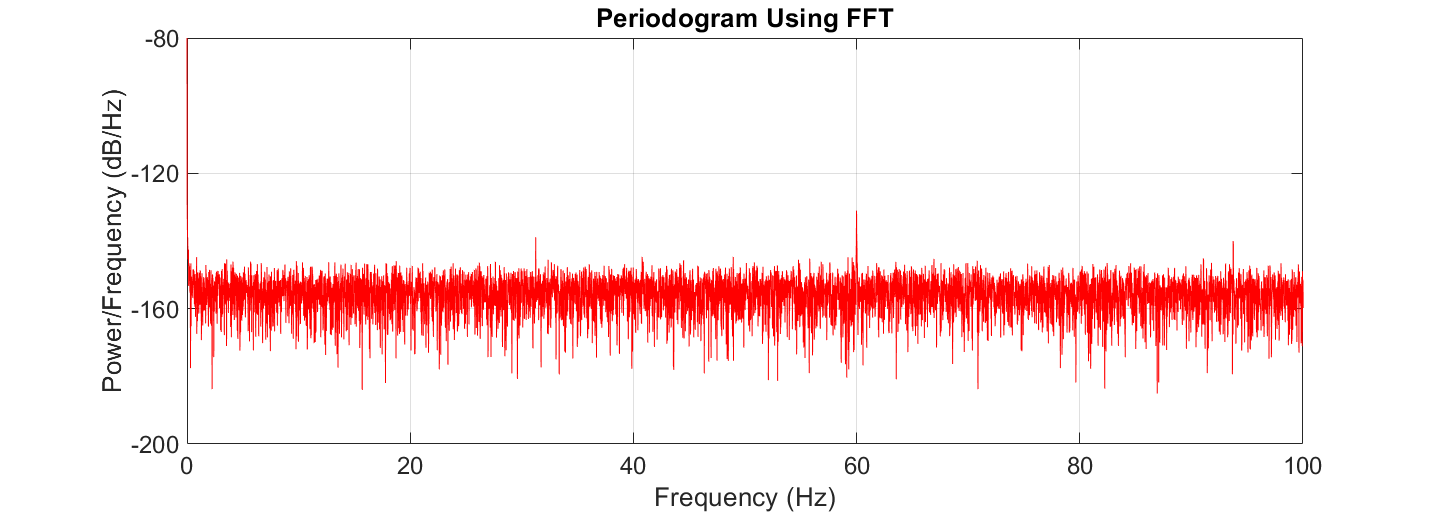

plot(freq,10*log10(dpsd),'r');
set(gca,'XLim',[0,100],'XTick',[0:20:100],'YLim',[-200, -80],'YTick',[-200:40:-80],'FontName','Arial','FontSize',18)
set(gcf,'position',[200 200 1440 512]);
title('Periodogram Using FFT');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

disp(['Vrms calculation: ',num2str(vnrms)]);

Vrms calculation: 2.2838e-05


## The followings are PSD templates

## FFT

dft = fft(data);
dft = dft(1:N/2+1);
dpsd = (1/(Fs_calc*N)) * abs(dft).^2;
dpsd(2:end-1) = 2*dpsd(2:end-1);
freq = 0 : Fs_calc/N : Fs_calc/2;
subplot(row,col,1);
plot(freq,10*log10(dpsd),'r');
set(gca,'XLim',[0,100],'XTick',[0:20:100],'YLim',[-200, -60],'YTick',[-200:20:-60],'FontName','Arial','FontSize',18)
set(gcf,'position',[200 200 1440 512]);
title('Periodogram Using FFT');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
%legend('ePhys to REF Periodogram with FFT');
grid ON;

## Periodogram

subplot(row,col,2);
periodogram(data,rectwin(N),N,Fs_calc);
set(gca,'XLim',[0,100],'XTick',[0:20:100],'YLim',[-200, -60],'YTick',[-200:20:-60],'FontName','Arial','FontSize',18)
set(gcf,'position',[200 200 1440 512]);
title('Periodogram Using Periodogram');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
h = get(gca, 'Children');
set(h(1), 'Color', 'r');
grid on;

## Pwelch

subplot(row,col,3);
[pxx,f] = pwelch(data,rectwin(N),0,N,Fs,'r');
plot(f,10*log10(pxx));
set(gca,'XLim',[0,100],'XTick',[0:20:100],'YLim',[-200, -60],'YTick',[-200:20:-60],'FontName','Arial','FontSize',18)
set(gcf,'position',[200 200 1440 512]);
title('Periodogram Using Pwelch');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
h = get(gca, 'Children');
set(h(1), 'Color', 'r');
grid on;

## Noise calculation function

function [dpsd, freq, Vnrms] = psd_rms(data,Fs,gain,fl,fh)
    N = length(data);
    dFT = fft(data);       % fft
    dFT = dFT(1:N/2+1);     % DC to Nyquist 
    dFT = dFT/gain;
    dpsd = (1/(Fs*N)) * abs(dFT).^2;  % periodogram
    dpsd(2:end-1) = 2*dpsd(2:end-1);      % factor of 2 to conserve power
    freq = 0:Fs/N:Fs/2;
    
    % Noise calculation presented in uVrms
    flidx = round(fl*N/Fs)+1;
    fhidx = round(fh*N/Fs)+1;
    df = freq(fhidx) - freq(fhidx-1);
    BW = flidx:fhidx; 
    Vnrms = sqrt(sum(dpsd(BW)*(df)));   
end